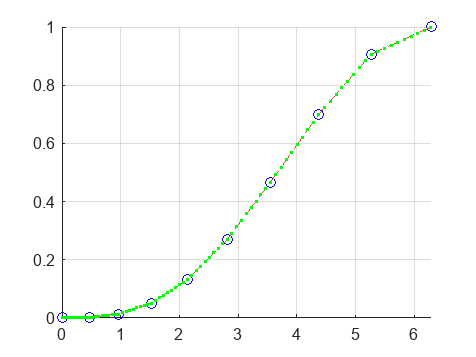

clear, clc; 
close all; 

%constant variables
n_1 = 10;
del_1 = .4186;
% n_2 = 20;
% del_2 = .1106;
% n_3 = 40;
% del_3 = .0146;
k = 1.1;
theta_one = ones(1, n_1);
% theta_two = ones(1, n_2);
% theta_three = ones(1, n_3);

%generating domain points
theta_one(1) = 0;


theta_one(n_1) = 2*pi();

for i = 1:n_1-2
    theta_one(i+1) = theta_one(i) + del_1*(k^i);
end

%generating range points
f_1 = sin(theta_one./4).^3;

s = cell(n_1-1,1);

for j = 2:n_1
    m = (f_1(j)-f_1(j-1))/(theta_one(j)-theta_one(j-1));
    x = linspace(theta_one(j-1),theta_one(j),10);
    b = f_1(j)-m*theta_one(j);
    y = m.*x + b;
    s{j-1} = [x;y];
end


%plotting
figure(1)
hold on; grid on;
plot(theta_one, f_1, 'bo',theta_one, f_1, '--')
for i = 1:n_1-1
    plot(s{i}(1,:),s{i}(2,:),'.g')
end